%%%%%%%
% Розрахунок пропукання атмосфери для нахилених трас
%%%%%%%
script
clear, clc;
% return;

# Дано:

%% Дано (загальне):

% Дата:
date.in = '15-08-2020 12:00:00';
% Часовий пояс:
date.tzone = '+03:00';

#### Кут нахилу [°]: 

% Кут спостереження відносно горизонту, [°]
theta = 0; 

#### Відносна вологість повітря [%]:

% Відносна вологість повітря, %
Earth.RH = 50;

#### Висота над рівнем моря [км]:

% Висота цілі над рівнем моря, [км]
% Київ 0.175 км
Earth.h0 = 0;

% Висота атмосфери, км
Earth.H = 20;

#### Діапазон довжин хвиль [мкм] (0.3 - 14):

% Діапазон довжин хвиль (0.3 - 14.0), мкм
target.l_min = 0.3;
target.l_max = 14;

% Земна широта і довгота знаходження цілі, [°]
% Київ: 50°27′00″ пн. ш. 30°31′25″ сх. д. 
Earth.lat.deg = 50.45;
Earth.lon.deg = 30.524;

#### Метеорологічна дальність видимості [км]:

% Метеорологічна дальність видимості, км
Earth.d_v = 20;

#### Темпаратура повітря на рівні моря [°C]:

% Темпаратура повітря на рівні моря [K]
% f_i = @(h) interp1(dataHT{1}, dataHT{2}, h);
% t_air = f_i(0);
% clear f_i;
% t_air = data.HT{2}(1);
t_air_c = 20;
t_air = t_air_c + 273.15;

#### Кількість точок для графіка:

% Кількість точок для графіка
params.N_point = 100;

#### Кількість довжин трас:

% Кількість точок для графіка
params.N_range = 18;

% Кількість "потоків"
params.N_thread = 10;
% Точність розрахунку інтегралів
params.tol = 0.00001;

% Упругість начисених парів води, для коеф. проп. парами води
params.method = 0; % апроксимація
% method = 1; % табличні дані [-50,+50]°С

#### Довжина траси [км]

% Відстань траси, яке проходить світло
% range = BorderOfLayer(H, theta, h_0, R_k); % до межі атмосфери, км
% range = 16;  % довжина траси, км

range_min = 0;
range_max = 1.852;
range = linspace(range_min, range_max, params.N_point);
range_array = linspace(range_min, range_max, params.N_range);
% clear range_min range_max;

#### Ефективна довжина шляху (профіль):

***true*** - сферичний профіль атмосфери; ***false*** - горизонтальний профіль атмосфери;

% Ефективна довжина шляху
% params.type = 0; % горизонтальний профіль атмосфери
% params.type = 1; % сферичний профіль атмосфери
params.type = true;

#### Спектри довжин хвиль [мкм]:

% спектр довжин хвиль
target.lamda = linspace(target.l_min, target.l_max, params.N_point)';

% спектральні діапазони
% target.sp = [3.0, 5.0;
%     3.8, 4.2;
%     4.4, 5.6;
%     3.8, 5.6;
%     8.0, 14.0];

clear target.sp;

target.sp(1, 1) = 0.3; target.sp(1, 2) = 0.8;
lamda_temp_min = 3; lamda_temp_max = 5; addData = true;
if (addData)
    target.sp(size(target.sp, 1) + 1, 1) = lamda_temp_min;
    target.sp(size(target.sp, 1), 2) = lamda_temp_max;
end
lamda_temp_min = 8; lamda_temp_max = 14; addData = true;
if (addData)
    target.sp(size(target.sp, 1) + 1, 1) = lamda_temp_min;
    target.sp(size(target.sp, 1), 2) = lamda_temp_max;
end
lamda_temp_min = 3.2; lamda_temp_max = 3.2; addData = true;
if (addData)
    target.sp(size(target.sp, 1) + 1, 1) = lamda_temp_min;
    target.sp(size(target.sp, 1), 2) = lamda_temp_max;
end
lamda_temp_min = 4; lamda_temp_max = 4; addData = true;
if (addData)
    target.sp(size(target.sp, 1) + 1, 1) = lamda_temp_min;
    target.sp(size(target.sp, 1), 2) = lamda_temp_max;
end

clear addData lamda_temp_min lamda_temp_max;

% радіус кривизни Землі [км]
Earth.R_k = RadiusCurvature(Earth.lat.deg);
% радіус до поверхні Землі [км]
Earth.R_t = RadiusToSurface(Earth.lat.deg);

% Дані температури [K] і висоти [км]
data.HT = TemperatureData(Earth.H, Earth.lat.deg, Earth.lon.deg,...
    date.in, date.tzone, params.N_point);

% Дані температури [°C] і питомої кількості осадженої води
data.WV = WaterVaporData();

% Дані пропускання парів води і вуглекислого газу
[data.H2O, data.CO2] = LoadTransmittance();

% Земна широта і довгота [°]
Earth.lat.rad = deg2rad(Earth.lat.deg);
Earth.lon.rad = deg2rad(Earth.lon.deg);

# **Результати:**

% Ефективна довжина шляху
d_eff_h2o = EffectivePath(range, theta, "H2O", Earth.h0,...
    Earth.R_k, params);
d_eff_co2 = EffectivePath(range, theta, "CO2", Earth.h0,...
    Earth.R_k, params);
d_eff_sct = EffectivePath(range, theta, "Scat", Earth.h0,...
    Earth.R_k, params);
% clear type;
d_eff_h2o_a = EffectivePath(range_array, theta, "H2O", Earth.h0,...
    Earth.R_k, params);
d_eff_co2_a = EffectivePath(range_array, theta, "CO2", Earth.h0,...
    Earth.R_k, params);
d_eff_sct_a = EffectivePath(range_array, theta, "Scat", Earth.h0,...
    Earth.R_k, params);

% Коефіцієнт пропускання атмосфери за рахунок ослаблення
tau_h2o = TauH2O(target.lamda, d_eff_h2o, t_air, Earth.RH,...
    data.H2O, data.WV, params.method);
tau_co2 = TauCO2(target.lamda, d_eff_co2, t_air, data.CO2);
tau_m = tau_h2o .* tau_co2;

tau_h2o_a = TauH2O(target.lamda, d_eff_h2o_a, t_air, Earth.RH,...
    data.H2O, data.WV, params.method);
tau_co2_a = TauCO2(target.lamda, d_eff_co2_a, t_air, data.CO2);
tau_m_a = tau_h2o_a .* tau_co2_a;

% Коефіцієнт пропускання атмосфери за рахунок розсіювання
tau_scat = TauScat(target.lamda, d_eff_sct, Earth.d_v);
tau_rez = tau_m .* tau_scat;

tau_scat_a = TauScat(target.lamda, d_eff_sct_a, Earth.d_v);
tau_rez_a = tau_m_a .* tau_scat_a;
clear d_eff_h2o d_eff_co2 d_eff_sct;
clear d_eff_h2o_a d_eff_co2_a d_eff_sct_a;

% Пропускання в заданих діапазонах
for j = 1:size(tau_rez, 2)
    f_i = @(wl) interp1(target.lamda, tau_rez(:, j), wl);
    parfor i = 1:size(target.sp, 1)
        if (target.sp(i, 2) - target.sp(i, 1) ~= 0)
            tau_sp(j, i) = integral(f_i, target.sp(i, 1), target.sp(i, 2))...
                ./ (target.sp(i, 2) - target.sp(i, 1));
        else
            tau_sp(j, i) = f_i(target.sp(i, 1));
        end
    end
end

clear f_i j;
%clear tau_rez ;

% Підпис для легенди
for i = 1:size(target.sp, 1)
    if (target.sp(i, 2) - target.sp(i, 1) ~= 0)
        str_sp(i) = strcat("\tau_{", num2str(target.sp(i, 1)), "-",...
            num2str(target.sp(i, 2)),"}");
    else
        str_sp(i) = strcat("\tau_{", num2str(target.sp(i, 1)),"}");
    end
end

% Очищення
clear i t_air_c;
clear tau_co2 tau_h2o tau_m tau_scat tau_rez;

%%%%%%%%%%
% Графіки:
%%%%%%%%%%

#### Діапазон довжин хвиль для графіка [мкм]:

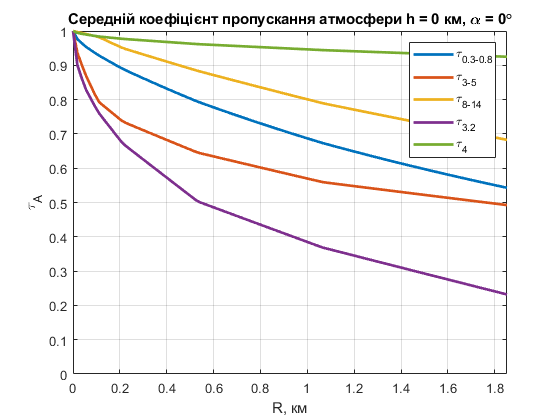

% Діапазон довжин хвиль (0.3 - 14.0), мкм
lamda_gr_min = 3;
lamda_gr_max = 5;

% Сумарний коефіцієнт пропускання атмосфери, 
% при заданому куті і довжині
figure('Name', "Середній коефіцієнт пропускання атмосфери",...
    'NumberTitle','off');
clf;
plot(range, tau_sp, 'LineWidth', 2);
grid on;
% title("Середній коефіцієнт пропускання атмосфери ");
title(strcat("Середній коефіцієнт пропускання атмосфери h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));
% title("\tau_\Sigma");
xlabel("R, км");
ylabel("\tau_A");
xlim([range_min, range_max]);
ylim([0, 1]);
legend(str_sp);

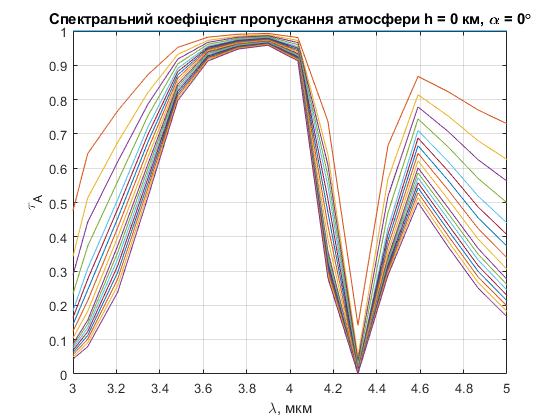


% Сумарний коефіцієнт пропускання атмосфери, 
% при заданому куті і довжині
figure('Name', "Спектральний коефіцієнт пропускання атмосфери",...
    'NumberTitle','off');
plot(target.lamda, tau_rez_a);
grid on;
% title("Спектральний коефіцієнт пропускання атмосфери");
title(strcat("Спектральний коефіцієнт пропускання атмосфери h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));
% title("\tau_\Sigma");
xlabel("\lambda, мкм");
ylabel("\tau_A");
xlim([lamda_gr_min, lamda_gr_max]);
ylim([0, 1]);

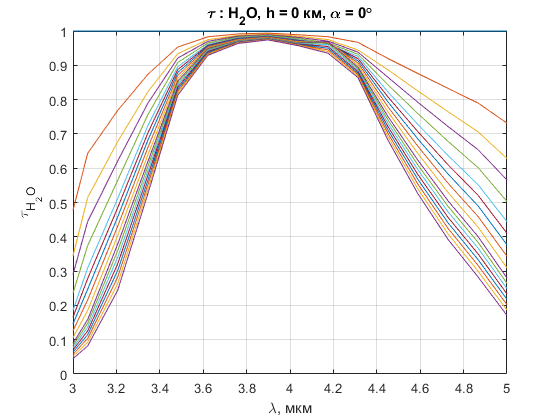


% Коефіцієнт пропускання атмосфери за рахунок ослаблення парами води, 
% при заданому куті і довжині
figure('Name', "Коефіцієнт пропускання атмосфери за рахунок ослаблення H_2O",...
    'NumberTitle','off');
clf;
% subplot('Position', [0.125 0.775 0.25 0.15]);
plot(target.lamda, tau_h2o_a);
grid on;
% title("Коефіцієнт пропускання атмосфери за рахунок ослаблення H_2O");
title(strcat("\tau : H_2O, h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));
xlabel("\lambda, мкм");
ylabel("\tau_{H_2O}");
xlim([lamda_gr_min, lamda_gr_max]);
ylim([0, 1]);

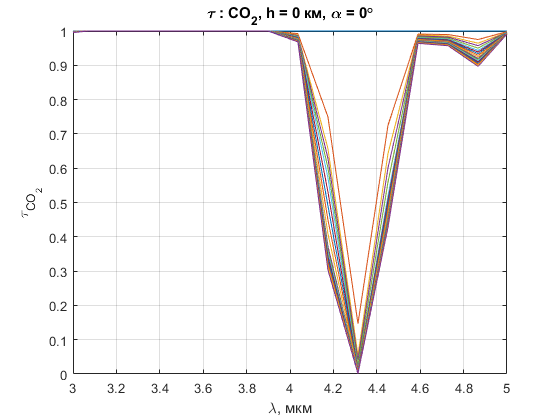


% Коефіцієнт пропускання атмосфери за рахунок ослаблення вуглекислим газом, 
% при заданому куті і довжині
figure('Name', "Коефіцієнт пропускання атмосфери за рахунок ослаблення CO_2",...
    'NumberTitle','off');
clf;
% subplot('Position', [0.125 0.45 0.25 0.15]);
plot(target.lamda, tau_co2_a);
grid on;
% title("Коефіцієнт пропускання атмосфери за рахунок ослаблення CO_2");
title(strcat("\tau : CO_2, h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));
xlabel("\lambda, мкм");
ylabel("\tau_{CO_2}");
xlim([lamda_gr_min, lamda_gr_max]);
ylim([0, 1]);

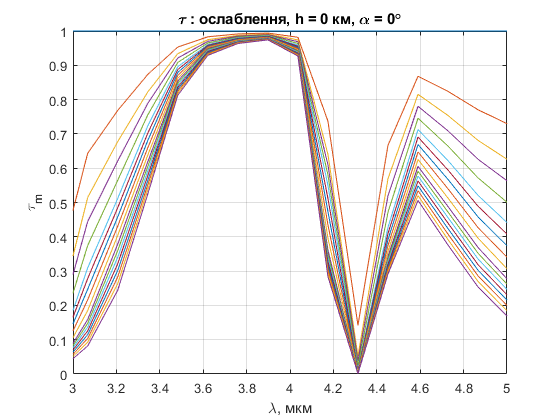


% Коефіцієнт пропускання атмосфери за рахунок ослаблення, 
% при заданому куті і довжині
figure('Name', "Коефіцієнт пропускання атмосфери за рахунок ослаблення",...
    'NumberTitle','off');
clf;
% subplot('Position', [0.125 0.125 0.25 0.15]);
plot(target.lamda, tau_m_a);
grid on;
% title("Коефіцієнт пропускання атмосфери за рахунок ослаблення");
title(strcat("\tau : ослаблення, h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));
xlabel("\lambda, мкм");
ylabel("\tau_m");
xlim([lamda_gr_min, lamda_gr_max]);
ylim([0, 1]);

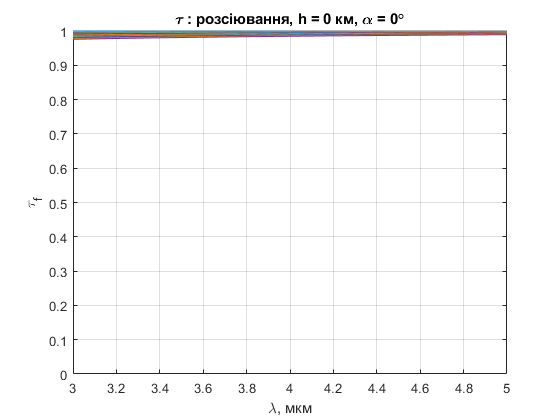


% Коефіцієнт пропускання атмосфери за рахунок затухання, 
% при заданому куті і довжині
figure('Name', "Коефіцієнт пропускання атмосфери за рахунок розсіювання",...
    'NumberTitle','off');
clf;
% subplot('Position', [0.5 0.775 0.25 0.15]);
plot(target.lamda, tau_scat_a);
grid on;
% title("Коефіцієнт пропускання атмосфери за рахунок розсіювання");
title(strcat("\tau : розсіювання, h = ",...
    num2str(Earth.h0), " км, \alpha = ", num2str(theta), "\circ"));

xlabel("\lambda, мкм");
ylabel("\tau_f");
xlim([lamda_gr_min, lamda_gr_max]);
ylim([0, 1]);


% clear theta tau_rez str_sp tau_sp;
% clear j range;